% Scoring constants
TimeMin = 3.7;
TimeMax = TimeMin * 1.5;
score_den = (TimeMax/TimeMin) - 1;      

% --- Vehicle Parameters ---
Mv = 285.763;                   % Vehicle Weight                     (kg)
r = 0.203;                      % Wheel Radius                       (m)
J = 1.2;                        % ESTIMATED Total Rotational Inertia (kg*m^2)
fd = 4.5;                       % Final Drive motor:tire             (Ratio) [baseline; each run overrides]
h_cg = 0.26035;                 % Height of Center of Gravity        (m)
W = 1.53035;                    % Wheelbase                          (m)
Grip_Fact = 1.0;                % Grip Factor of the Tire            [baseline; each run overrides]
Drive_Train = 0.89;             % Drivetain loss perecent

% --- Aerodynamics ---
A = 1;                          % Frontal Area                       (m^2)
rho = 1.225;                    % Air Density                        (kg/m^3)
Cd = 1;                         % Drag Coefficient
Cl = 3.8;                       % Lift Coefficient

% -- Static Loads --
cg_f = 0.734568;                % Front Axel to CG                   (m)
cg_r = 0.795782;                % Front Axel to CG                   (m)

% -- Control Params --
T_request = 150;                % Initial Driver Torque Request      (Nm)
Slip_Target = 0.13;             % Target Slip Ratio
Max_Wheel_Omega = 183.3;        % Maximum Wheel Angular Velocity     (rad/s)
Max_Motor_Torque = 150;         % Maximum Motor Torque               (Nm)
gravity = 9.80665;              % Accel due to Gravity Used          (m/s^2)
P = 5000;                       % Proportional in PID
I = 30;                         % Integral in PID
D = 0;                          % Derivative in PID
N = 0;                          % Filter Coefficient in PID

% -- Simulink --
timedomain = 10;                % Simulation Time (s)
modelName = 'TC_SIM';           % Model file: TC_SIM.slx

% -- Sweep definitions --
grips = 0.5:0.1:0.9;            % 10 values
fdrs  = linspace(2, 6, 49);     % 49 values, inclusive
nG = numel(grips);
nF = numel(fdrs);
nTotal = nG * nF;

% -- Prepare result storage --
time75 = NaN(nG, nF);                   % time to 75 m (s)
score  = NaN(nG, nF);                   % score
successMask = false(nG, nF);            % success flags
ig_idx = zeros(nTotal,1);
jf_idx = zeros(nTotal,1);

% -- Parallel pool --
pool = gcp('nocreate');
if isempty(pool)
    parpool('local', 16); % CHANGE TO NUMBER OF CORES YOU HAVE <----------------------------------------
end

% -- Build Simulation Inputs --
simIn(nTotal,1) = Simulink.SimulationInput(modelName); % preallocate
k = 0;
for ig = 1:nG
    for jf = 1:nF
        k = k + 1;
        ig_idx(k) = ig;
        jf_idx(k) = jf;

        si = Simulink.SimulationInput(modelName);
        % Per-run parameters
        si = si.setVariable('Grip_Fact', grips(ig));
        si = si.setVariable('fd',        fdrs(jf));
        % Baseline constants (transfer to workers)
        si = si.setVariable('Mv', Mv);
        si = si.setVariable('r', r);
        si = si.setVariable('J', J);
        si = si.setVariable('h_cg', h_cg);
        si = si.setVariable('W', W);
        si = si.setVariable('Drive_Train', Drive_Train);
        si = si.setVariable('A', A);
        si = si.setVariable('rho', rho);
        si = si.setVariable('Cd', Cd);
        si = si.setVariable('Cl', Cl);
        si = si.setVariable('cg_f', cg_f);
        si = si.setVariable('cg_r', cg_r);
        si = si.setVariable('T_request', T_request);
        si = si.setVariable('Slip_Target', Slip_Target);
        si = si.setVariable('Max_Wheel_Omega', Max_Wheel_Omega);
        si = si.setVariable('Max_Motor_Torque', Max_Motor_Torque);
        si = si.setVariable('gravity', gravity);
        si = si.setVariable('P', P);
        si = si.setVariable('I', I);
        si = si.setVariable('D', D);
        si = si.setVariable('N', N);
        % Model parameters
        si = si.setModelParameter('StopTime', num2str(timedomain));

        simIn(k) = si;
    end
end

% -- Run parallel simulations --
simOut = parsim(simIn, 'ShowProgress','on', 'UseFastRestart','on');

[12-Nov-2025 23:21:44] Checking for availability of parallel pool...
[12-Nov-2025 23:21:44] Starting Simulink on parallel workers...
[12-Nov-2025 23:21:44] Configuring simulation cache folder on parallel workers...
[12-Nov-2025 23:21:44] Loading model on parallel workers...
[12-Nov-2025 23:21:45] Running simulations...
[12-Nov-2025 23:21:49] Completed 1 of 490 simulation runs
[12-Nov-2025 23:21:49] Received simulation output (size: 2.13 MB) for run 1 from parallel worker.
[12-Nov-2025 23:21:49] Completed 2 of 490 simulation runs
[12-Nov-2025 23:21:49] Received simulation output (size: 3.22 MB) for run 2 from parallel worker.
[12-Nov-2025 23:21:49] Completed 3 of 490 simulation runs
[12-Nov-2025 23:21:49] Received simulation output (size: 4.48 MB) for run 3 from parallel worker.
[12-Nov-2025 23:21:49] Completed 4 of 490 simulation runs
[12-Nov-2025 23:21:49] Received simulation output (size: 6.05 MB) for run 4 from parallel worker.
[12-Nov-2025 23:21:50] Completed 5 of 490 simulation ru


%% ------------------ Extract results safely (robust to log format) ------------------
for k = 1:nTotal
    ig = ig_idx(k);
    jf = jf_idx(k);

    t75 = NaN; % default
    try
        % Detect if this run errored using SimulationMetadata.ExecutionInfo
        hadErr = false;
        try
            execInfo = simOut(k).SimulationMetadata.ExecutionInfo;
            if ~isempty(execInfo)
                if isfield(execInfo,'StopEvent')
                    hadErr = strcmpi(char(execInfo.StopEvent), 'Error');
                end
                if ~hadErr && isfield(execInfo,'ErrorMessage')
                    hadErr = ~isempty(execInfo.ErrorMessage);
                end
            end
        catch
            hadErr = false;
        end

        if ~hadErr
            gotData = false;

            % (a) Nested struct named 'simout'
            if isprop(simOut(k), 'simout')
                try
                    s = simOut(k).simout;
                    TimeVec = s.v_velocity.Time;
                    DistVec = s.v_distance.Data;
                    gotData = true;
                catch
                end
            end

            % (b) Direct logged signals on SimulationOutput
            if ~gotData && isprop(simOut(k), 'v_velocity') && isprop(simOut(k), 'v_distance')
                try
                    TimeVec = simOut(k).v_velocity.Time;
                    DistVec = simOut(k).v_distance.Data;
                    gotData = true;
                catch
                end
            end

            % (c) logsout Dataset (last resort)
            if ~gotData && isprop(simOut(k),'logsout') && ~isempty(simOut(k).logsout)
                try
                    ds = simOut(k).logsout;
                    vvel = ds.getElement('v_velocity');
                    vdis = ds.getElement('v_distance');
                    TimeVec = vvel.Values.Time;
                    DistVec = vdis.Values.Data;
                    gotData = true;
                catch
                end
            end

            if gotData
                % Ensure column vectors and same length
                TimeVec = TimeVec(:);
                DistVec = DistVec(:);
                nmin = min(numel(TimeVec), numel(DistVec));
                if nmin > 0
                    t75 = time_to_distance75(TimeVec(1:nmin), DistVec(1:nmin));
                end
            end
        end
    catch
        % Any access/logging issues => NaN
    end

    time75(ig, jf) = t75;

    if ~isnan(t75)
        score(ig, jf) = 95.5 * ((TimeMax / t75) - 1) / score_den + 4.5;
        successMask(ig, jf) = true;
    else
        score(ig, jf) = NaN;
        successMask(ig, jf) = false;
    end
end

% -- Quick diagnostics (helps if plots look empty) --
nSuccess = nnz(successMask);
if nSuccess == 0
    fprintf(2,'[WARN] No successful runs. Showing first few error messages (if available):\n');
    for k = 1:min(5, nTotal)
        try
            ex = simOut(k).SimulationMetadata.ExecutionInfo;
            if ~isempty(ex) && isfield(ex,'ErrorMessage') && ~isempty(ex.ErrorMessage)
                fprintf(2,'  #%d: %s\n', k, ex.ErrorMessage);
            end
        catch
        end
    end
else
    fprintf('[OK] %d/%d runs produced valid 75 m times.\n', nSuccess, nTotal);
end

[OK] 245/245 runs produced valid 75 m times.


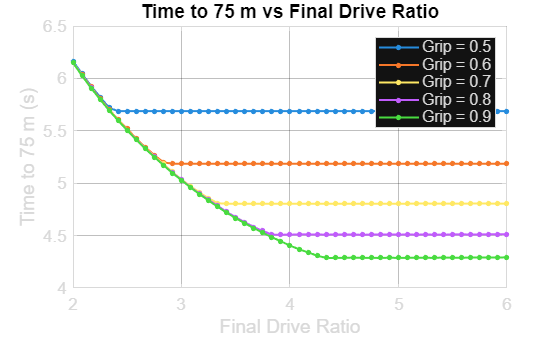


%% ------------------ Plot: Time to 75 m vs Final Drive ------------------
set(groot, 'defaultAxesFontSize', 13);
set(groot, 'defaultLineLineWidth', 1.5);

% --- Black-on-white figure theme (applies to all figures in this session) ---
set(groot, ...
    'defaultFigureColor',   'white', ...
    'defaultAxesColor',     'white', ...
    'defaultAxesXColor',    'black', ...
    'defaultAxesYColor',    'black', ...
    'defaultAxesZColor',    'black', ...
    'defaultTextColor',     'black', ...
    'defaultAxesGridColor', 'black');


figure;
hold on; grid on; box on;
h = gobjects(nG,1);
% --- Figure 1 loop (Time vs FD) ---
for ig = 1:nG
    y = time75(ig, :);
    if all(isnan(y)); continue; end
    h(ig) = plot(fdrs, y, '-', 'Marker','.', 'MarkerSize',12);  % dots on each point
end
xlabel('Final Drive Ratio');
ylabel('Time to 75 m (s)');
title('Time to 75 m vs Final Drive Ratio');
validLeg = ~arrayfun(@(hi) isempty(hi) || ~isgraphics(hi), h);
if any(validLeg)
    legend(h(validLeg), arrayfun(@(g)sprintf('Grip = %.1f', g), grips(validLeg), 'UniformOutput', false), ...
           'Location','northeast');
end
saveas(gcf, 'figure_time_vs_fd.png');

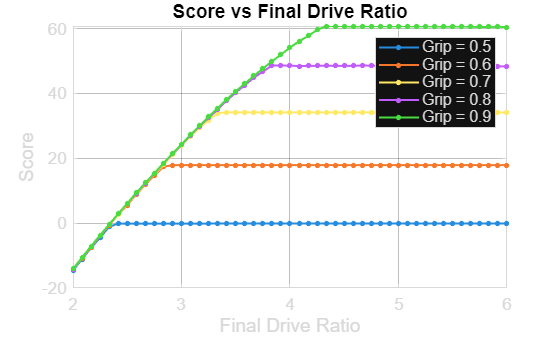


%% ------------------ Plot: Score vs Final Drive ------------------
figure;
hold on; grid on; box on;
h2 = gobjects(nG,1);
% --- Figure 2 loop (Score vs FD) ---
for ig = 1:nG
    y = score(ig, :);
    if all(isnan(y)); continue; end
    h2(ig) = plot(fdrs, y, '-', 'Marker','.', 'MarkerSize',12); % dots on each point
end
xlabel('Final Drive Ratio');
ylabel('Score');
title('Score vs Final Drive Ratio');
validLeg2 = ~arrayfun(@(hi) isempty(hi) || ~isgraphics(hi), h2);
if any(validLeg2)
    legend(h2(validLeg2), arrayfun(@(g)sprintf('Grip = %.1f', g), grips(validLeg2), 'UniformOutput', false), ...
           'Location','northeast');
end
saveas(gcf, 'figure_score_vs_fd.png');


%% ------------------ Save results table ------------------
[GF_grid, FD_grid] = ndgrid(grips, fdrs);
T = table( GF_grid(:), FD_grid(:), time75(:), score(:), ...
    'VariableNames', {'Grip_Fact','fd','time75_s','score'} );
writetable(T, 'sweep_results.csv');

%% ------------------ Summary ------------------
fprintf('Sweep complete: %d successful runs out of %d total combinations.\n', nSuccess, nTotal);

Sweep complete: 245 successful runs out of 245 total combinations.


fprintf('Figures saved: figure_time_vs_fd.png, figure_score_vs_fd.png\n');

Figures saved: figure_time_vs_fd.png, figure_score_vs_fd.png


fprintf('Results table saved: sweep_results.csv\n');

Results table saved: sweep_results.csv



%% ------------------ Helper function ------------------
function t = time_to_distance75(Time, Dist)
    idx = find(Dist >= 75, 1, 'first');
    if isempty(idx)
        t = NaN;
    else
        t = Time(idx);
    end
end
